# Visual degrees to retinal mm

It is sometimes necessary to convert measurements made along the retina from one set of units (degrees of visual angle) to another (millimeters). While there are rules-of-thumb for this conversion (e.g., 0.3 mm / degree), the precise value is complicated to obtain. This is because of individual varation in the ellipsoidal dimensions of the retina, as well as in the optics and accommodative state of the eye.

First set some values for the simulations below:

% Try adjusting these values in the demo
wavelength = 555;
sphericalAmetropia = -5; % Changes in this value will substantially alter the mapping
hPos = 5:5:50;  % The range of visual field eccentricities

% Defining some variables here that we will need later
d = nan(size(hPos));
rayOriginDistance = Inf;

## Drasdo & Fowler 1974 model eye

We create the eye model, and then measure the geodetic distance between the fovea and the point of retinal intersection of nodal rays arising from locations in the visual field.

% Create the eye
eye = modelEyeParameters('spectralDomain',wavelength,'species','Drasdo');

% Extract some landmarks
foveaField = eye.landmarks.fovea.degField;
foveaCoord = eye.landmarks.fovea.coords';
angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);

% Loop over horizontal field positions
for hh = 1:length(hPos)
    fieldPos = [hPos(hh) 0]+foveaField;
    rayPath = calcNodalRayFromField(eye,fieldPos,1000,angleReferenceCoord,distanceReferenceCoord);
    d(hh) = quadric.geodesic(eye.retina.S,[],[],rayPath(:,end),foveaCoord);
end 

% Plot
figure
plot([0 hPos],[0 d],'*-k');
xlabel('visual field degrees')
ylabel('geodetic distance from fovea [mm]')
hold on

## The current model eye

Repeat this calculation using the current model eye:

% Create the eye
eye = modelEyeParameters('spectralDomain',wavelength,'sphericalAmetropia',sphericalAmetropia);

% Extract some landmarks
foveaField = eye.landmarks.fovea.degField;
foveaCoord = eye.landmarks.fovea.coords';
angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);

% Loop over horizontal field positions
for hh = 1:length(hPos)
    fieldPos = [hPos(hh) 0]+foveaField;
    rayPath = calcNodalRayFromField(eye,fieldPos,1000,angleReferenceCoord,distanceReferenceCoord);
    d(hh) = quadric.geodesic(eye.retina.S,[],[],rayPath(:,end),foveaCoord);
end

% Plot
plot([0 hPos],[0 d],'o-r')

## The Watson approximation

Watson 2014 JoV provided an approximation to the Drasdo & Fowler in Eq A5. We can add that line in green.

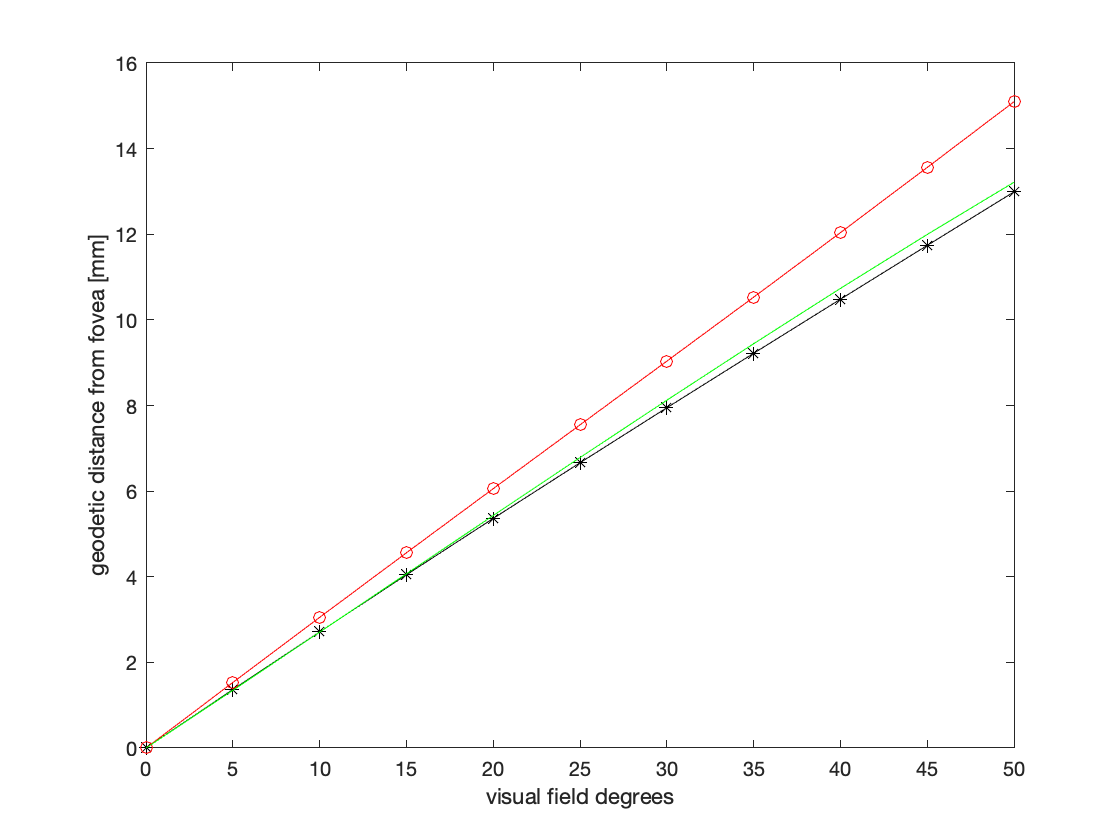

watsonA5 = @(deg) 0.268.*deg + 0.0003427.*deg.^2 - 8.3309e-6.*deg.^3;
d = watsonA5(hPos);
plot([0 hPos],[0 d],'-g')

If we explore different values for the spherical ametropia of the eye, we find that the standard Drasdo & Fowler solution is similar to what the current model would predict for a +3 hyperopic eye.